# Modelling Bacterial Growth using DLA

Let us first do this with 1000 steps.

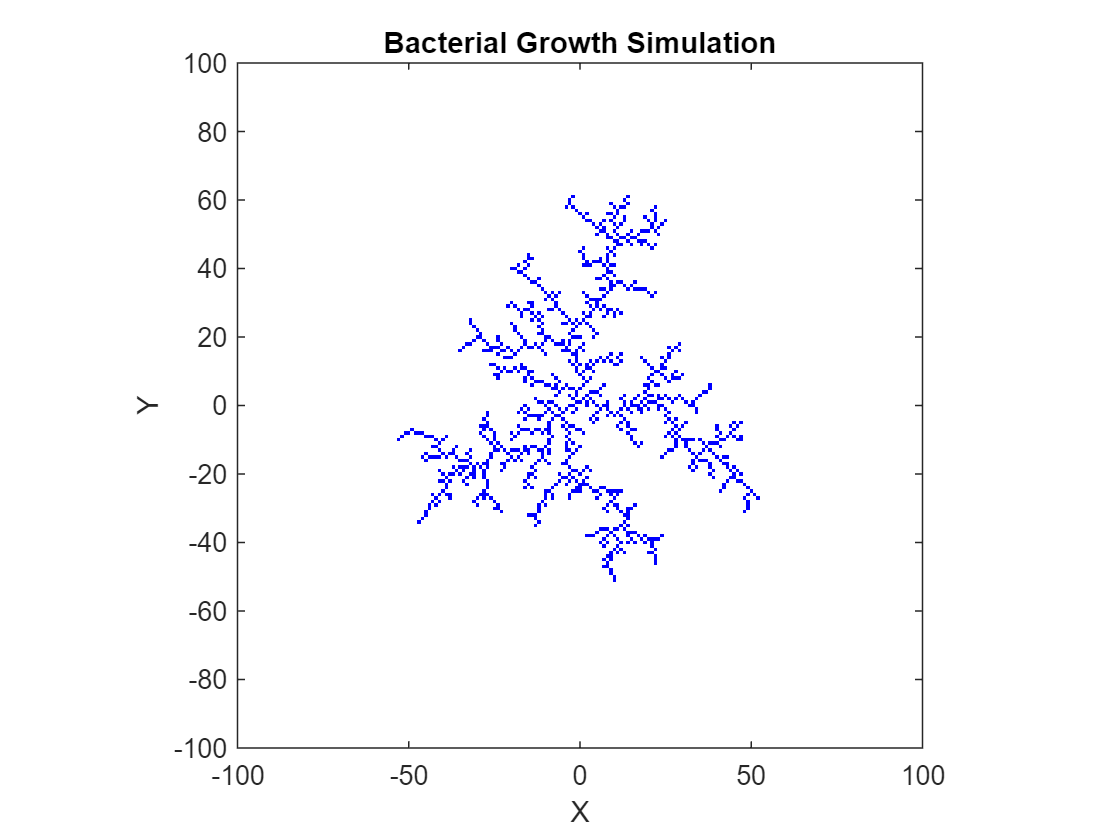

DLA_BacteriumGrowth(200, 1000, 1);

Similarly, for 2500 steps.

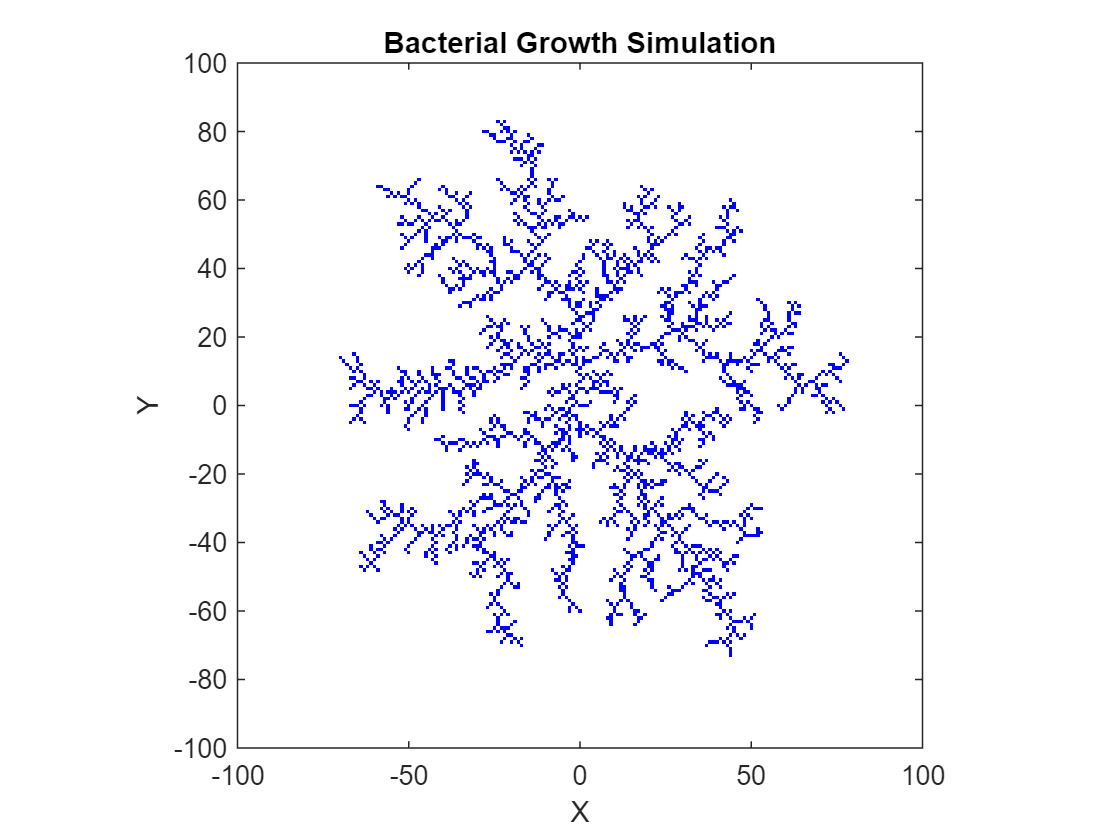

DLA_BacteriumGrowth(200, 2500, 1);

Now, let us do this with 5000 steps.

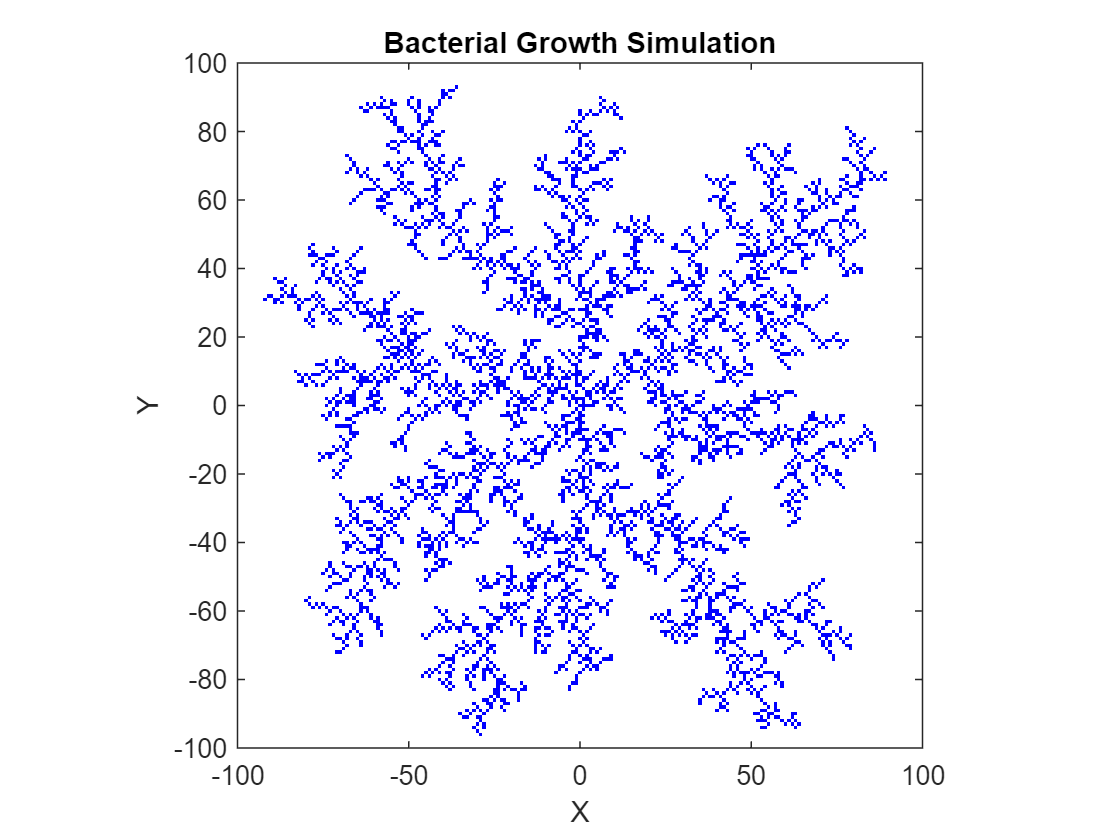

DLA_BacteriumGrowth(200, 5000, 1);

Again, the 10000 steps.

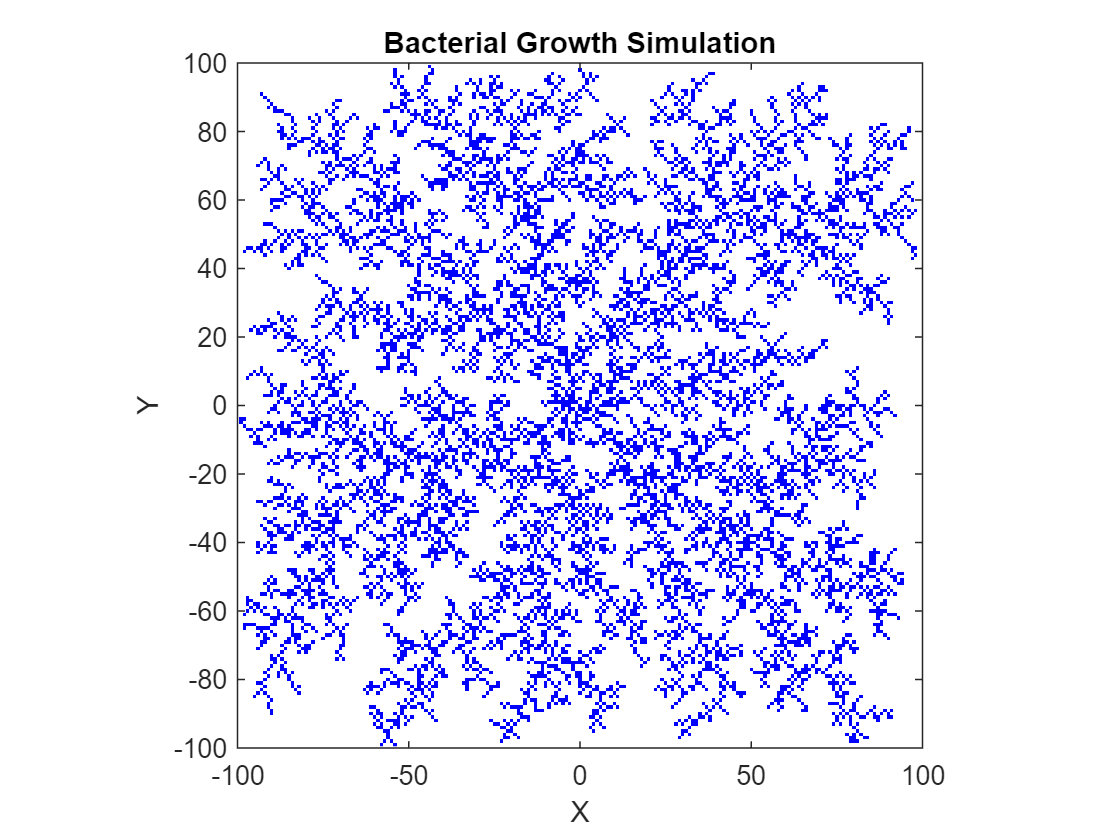

DLA_BacteriumGrowth(200, 10000, 1);

Finally, with 50000 steps.

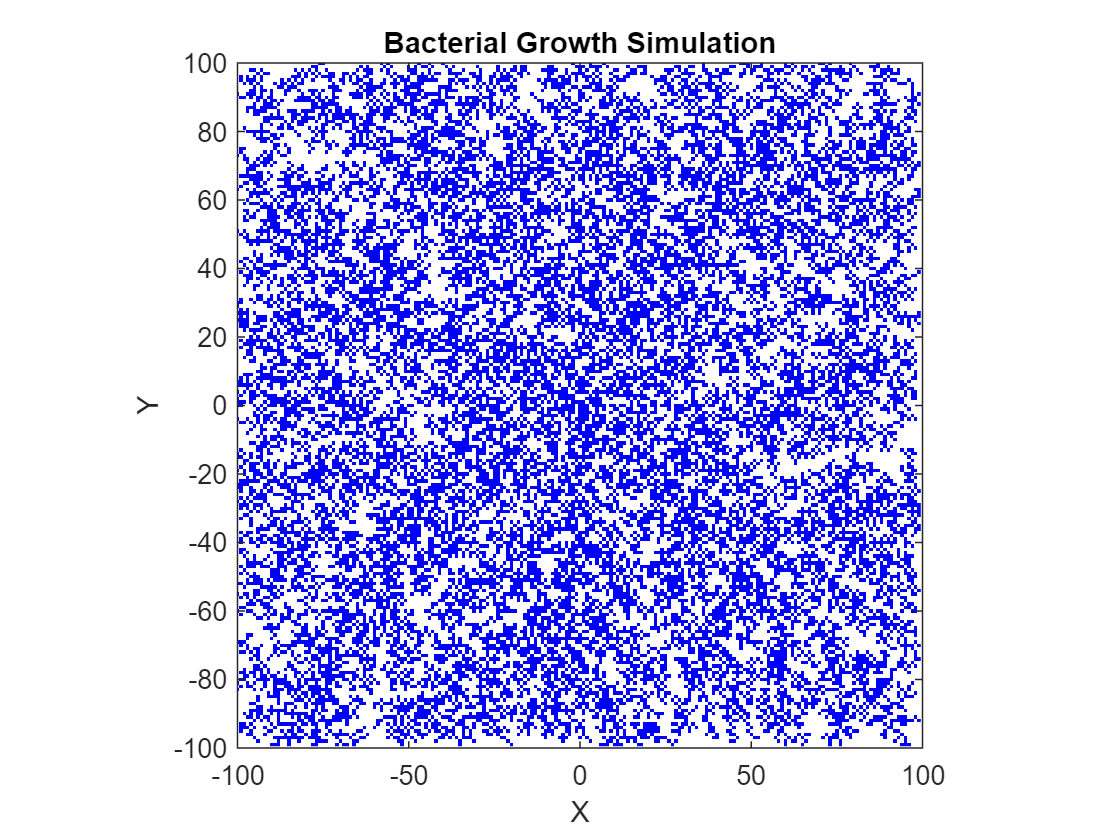

DLA_BacteriumGrowth(200, 25000, 1);

Here we define the function to perform the DLA algorithm.

function DLA_BacteriumGrowth(gridSize, numParticles, stickDistance)
    % Initialize grid
    grid = zeros(gridSize);

    % Place seed particle at the center of the grid
    startX = gridSize/2;
    startY = gridSize/2;
    grid(startX, startY) = 1;

    % Main simulation loop
    for i = 1:numParticles
        % Generate a random position for the new particle
        x = randi([1, gridSize]);
        y = randi([1, gridSize]);

        % Check if the new particle sticks to the existing cluster
        while true
            % Check if any neighboring cells are occupied
            neighbors = grid(max(1, x-1):min(gridSize, x+1), max(1, y-1):min(gridSize, y+1));
            if any(neighbors(:) == 1)
                % Particle sticks to the cluster
                grid(x, y) = 1;
                break;
            end

            % Move the particle randomly
            direction = randi([1, 4]);
            if direction == 1
                x = max(1, x - 1);  % Move up
            elseif direction == 2
                x = min(gridSize, x + 1);  % Move down
            elseif direction == 3
                y = max(1, y - 1);  % Move left
            else
                y = min(gridSize, y + 1);  % Move right
            end

            % Check if the particle is close enough to stick
            if grid(x, y) == 1
                % Particle sticks to the cluster
                grid(x, y) = 1;
                break;
            end
        end
    end

    % Display the final grid
    figure;
    colormap([1 1 1; 0 0 1]);  % Set colormap: white background, blue particles
    imagesc((-gridSize/2:gridSize/2-1), (-gridSize/2:gridSize/2-1), grid);
    axis equal;
    axis([-gridSize/2 gridSize/2 -gridSize/2 gridSize/2]);  % Set y-axis limits
    title('Bacterial Growth Simulation');
    xlabel('X');
    ylabel('Y');

    % Reverse the y-axis tick labels
    yticks = get(gca, 'YTick');
    yticklabels = arrayfun(@(x) sprintf('%d', -x), yticks, 'UniformOutput', false);
    set(gca, 'YTickLabel', yticklabels);
end